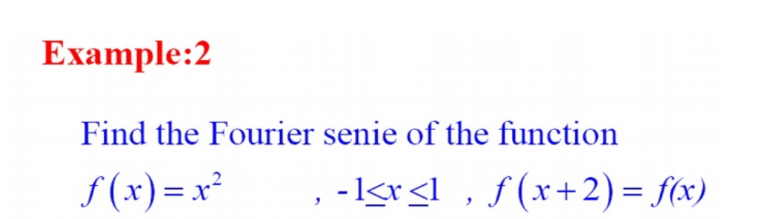

clear;clf;
syms x n;
f = x^2;
a0 = eval(int(f,x,[-1 1]))

a0 = 0.6667

assume(n,"integer")
an = vpa(simplify(int(f*cos(n*x*pi),x,[-1 1])),3)

$$an = \frac{0.405\,{\left(-1.0\right)}^{n}}{n^{2}}$$

bn = vpa(simplify(int(f*sin(n*x*pi),x,[-1 1])),3)

$$bn = 0.0$$

f0 = vpa(simplify(an*cos(n*x*pi)+bn*sin(n*x*pi)),3)

$$f0 = \frac{0.405\,{\left(-1.0\right)}^{n}\,\cos\left(3.14\,n\,x\right)}{n^{2}}$$

fn = symsum(simplify(an*cos(n*x*pi)+bn*sin(n*x*pi)),n,1,inf)

$$fn = \left\{ \begin{array}{cl} 0.20264236728689866140484809875488\,\mathrm{polylog}\left(2,-1.0\,{\mathrm{e}}^{-3.1415926535897932384626433832795\,x\,\mathrm{i}}\right)+0.20264236728689866140484809875488\,\mathrm{polylog}\left(2,-1.0\,{\mathrm{e}}^{3.1415926535897932384626433832795\,x\,\mathrm{i}}\right) & \text{ if }x\in \mathbb{R} \end{array}\right.$$

harm = 3;
for i = 1:harm
    fx = a0/2+symsum(f0,n,[1 i]);
    subplot(harm+1,1,i)
    fplot(fx,[-1 1])
    title('Harmonic')
    xlabel('time')
end
hold on

**Plot Input**

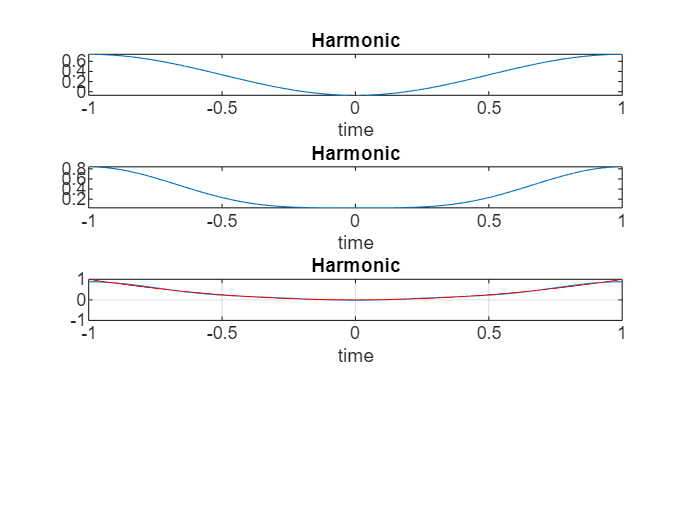

t = -1:1/1000:1;
y = t.^2;
plot(t,y,'r')
ylim([-1 1])
grid on